Un kernel es una funcion que me va indicando la importancia de lo que va pasando.

El kernel ayuda a recrear la funcion de densidad.

% Fuuncion real paramericamente estimada
x = 10+2*randn(1000,1);
li = min(x);
ls = max(x);
xm = li:0.05:ls;
dt = normpdf(xm,10,2);
plot(xm,dt)

%Estimacion con un kernel uniforme MatLab
pd_kernel = fitdist(x,'Kernel')

pd_kernel =   KernelDistribution

    Kernel = normal
    Bandwidth = 0.538447
    Support = unbounded


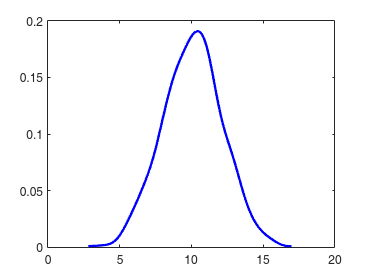

pdf_kernel = pdf(pd_kernel,xm);
plot(xm,pdf_kernel,'Color','b','LineWidth',2);


%Añadir codigo Henry

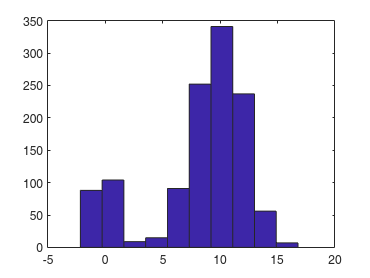

x1 = 10 + 2*randn(1000,1);
x2 = randn(200,1);

x = [x1
    x2];

hist(x)

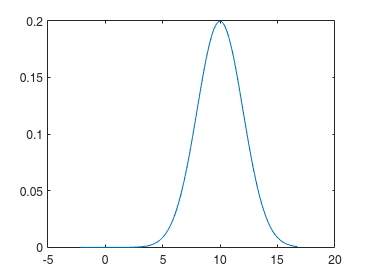


%No se podria estimar de manera parametrica
li = min(x);
ls = max(x);
xm = li:0.05:ls;
dt = normpdf(xm,10,2);
plot(xm,dt)


%Estimacion con un kernel uniforme MatLab
pd_kernel = fitdist(x,'Kernel')

pd_kernel =   KernelDistribution

    Kernel = normal
    Bandwidth = 0.69815
    Support = unbounded


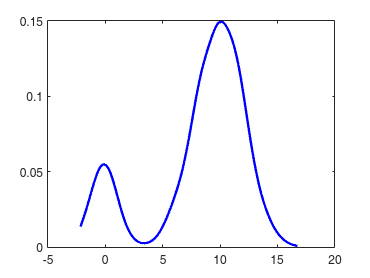

pdf_kernel = pdf(pd_kernel,xm);
plot(xm,pdf_kernel,'Color','b','LineWidth',2);